%%按起始终止点拆分数据
unique_attrs = unique(data2(:,5));
% 创建一个结构体数组，每个元素对应一个属性值
for i = 1:numel(unique_attrs)
    attr = unique_attrs{i,1};
    idx = ismember(data2{:,5}, attr);
    % 获取该属性值对应的行索引
    result(i).Attribute = attr; 
    % 存储属性值
    result(i).Data = data2(idx, :); 
    % 存储数据
end

%%将"DC14DC10","DC20DC35","DC25DC62"分别存在aa,bb,cc三个变量中
for i=1:1049
    if result(i).Attribute=="DC14DC10"
        aa=result(i);
    end
    if result(i).Attribute=="DC20DC35"
        bb=result(i);
    end
    if result(i).Attribute=="DC25DC62"
        cc=result(i);
    end
end

%%按日期拆分数据
unique_attrs = unique(data2(:,3));
% 创建一个结构体数组，每个元素对应一个属性值
for i = 1:numel(unique_attrs)
    attr = unique_attrs{i,1};
    idx = ismember(data2{:,3}, attr);
    % 获取该属性值对应的行索引
    result2(i).Attribute = attr; 
    % 存储属性值
    result2(i).Data = data2(idx,:); 
    % 存储数据
end

b14e10=conventor(aa);
area(b14e10);
axis([0,800,0,150000]);
xlabel("Date");
ylabel("Transportation 14 to 10");

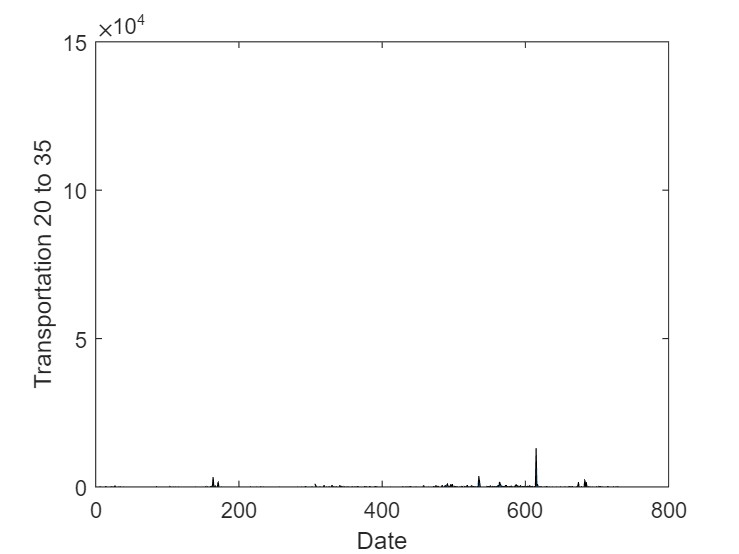

b20e35=conventor(bb);
area(b20e35);
axis([0,800,0,150000]);
xlabel("Date");
ylabel("Transportation 20 to 35");

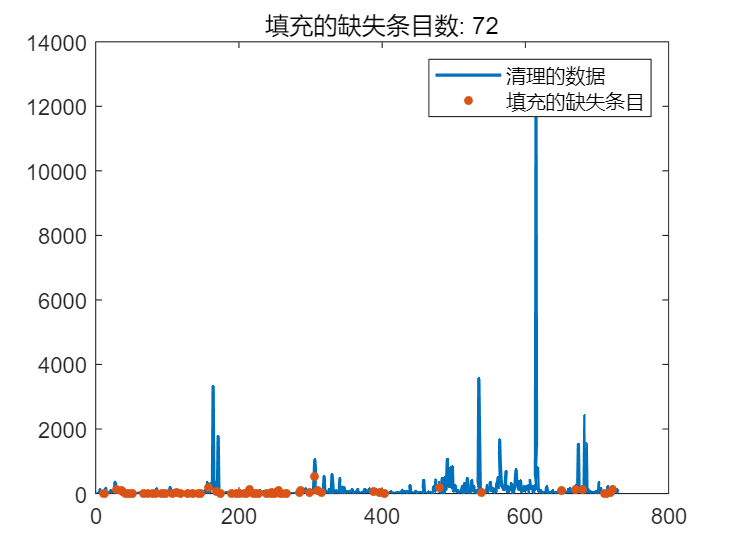

% 填充缺失数据
[cleanedData2,missingIndices2] = fillmissing(b20e35,"linear");

% 显示结果
clf
plot(cleanedData2,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","清理的数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices2),cleanedData2(missingIndices2),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices2))

hold off
legend

clear missingIndices2

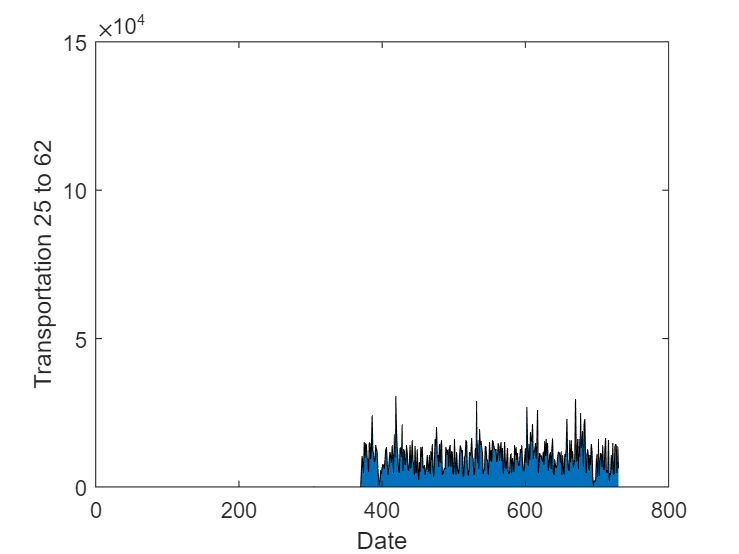

b25e62=conventor(cc);
area(b25e62);
axis([0,800,0,150000]);
xlabel("Date");
ylabel("Transportation 25 to 62");

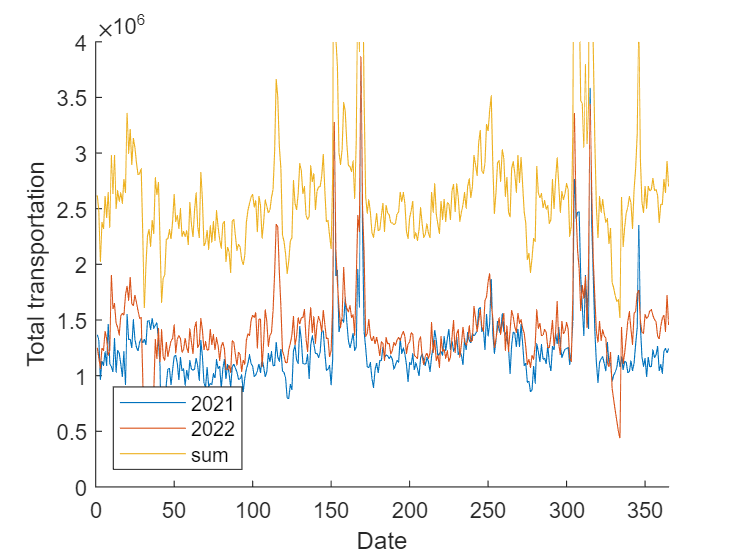

%%每天的总货物输送量
clf
x=1:365;
all=[1,730];
original_date=datetime(2021,1,1);
for i = 1:730
    all(days(result2(i).Data.VarName3 - original_date)+1)= sum(result2(i).Data.VarName4);
end
all2=all(366:end);
all3=all(1:365);
all4=all2+all3;
hold on
plot(x,all3,x,all2);
axis([0,365,0,4000000]);
axis([0,365,0,4000000]);
plot(all4);
legend({'2021','2022','sum'},'Location','southwest')
hold off
xlabel("Date");
ylabel("Total transportation");

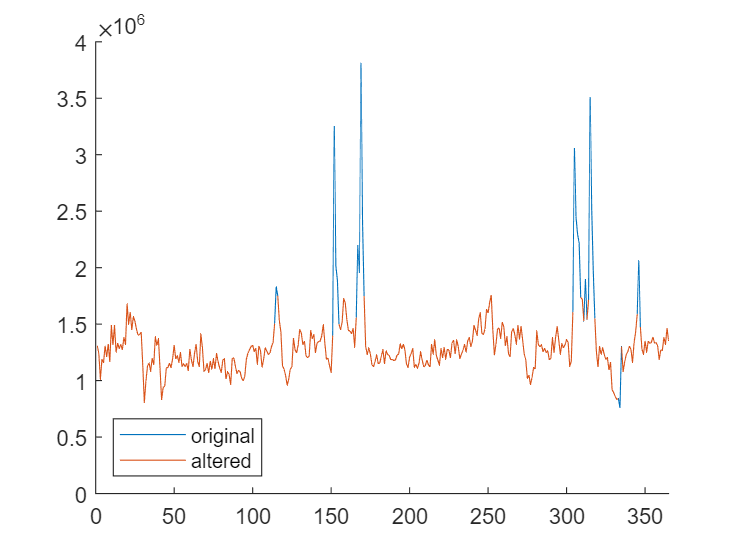

clf
hold on 
original=all4/2;
plot(original);%两年总值的平均
axis([0,365,0,4000000]);
axis([0,365,0,4000000]);
difference=mean(all2)-mean(all3);%后一年相对于前一年的平均增量
outliers = find(isoutlier(all4));
save=all4;
save2=all4;

mask = ones(size(save));
mask(outliers) = 0;
mask = logical(mask);
save(mask) = 0;

all4(outliers)=NaN;
altered=all4/2;
plot(altered);
legend({'original','altered'},'Location','southwest')
hold off

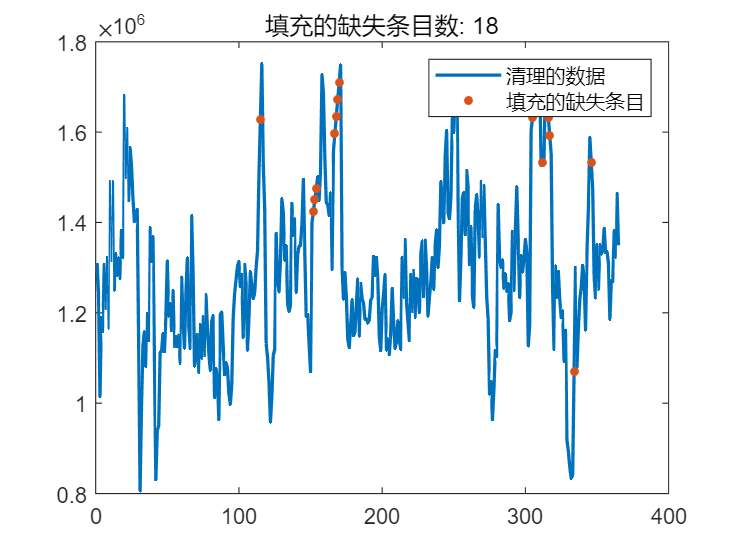

% 填充缺失数据
[cleanedData,missingIndices] = fillmissing(altered,"linear");

% 显示结果
clf
plot(cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","清理的数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices),cleanedData(missingIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices))

hold off
legend

clear missingIndices


A=[1:1:365]'

A =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


t=altered; %将所有因变量合并目标数据矩阵
[n1,n]=size(A) %%%%自变量的个数

n1 = 365

n = 1

[m,m1]=size(all) %%%%因变量的个数

m = 1

m1 = 730

p=A';  %将所有自变量合并得到输入数据矩阵
%利用premnmx函数对数据进行归一化
[pn,minp,maxp,tn,mint,maxt]=premnmx(p,t); % 对于输入矩阵p和输出矩阵t进行归一化处理

          Use MAPMINMAX instead, type HELP PREMNMX for bug warning.
 


u=ones(n,1);
dx=[-1*u,1*u];%归一化处理后最小值为-1，最大值为1
%BP网络训练
net=newff(dx,[n,50,m],{'tansig','tansig','purelin'},'traingdx'); %建立模型，并用梯度下降法训练．

          See help for NEWFF to update calls to the new argument list.
 


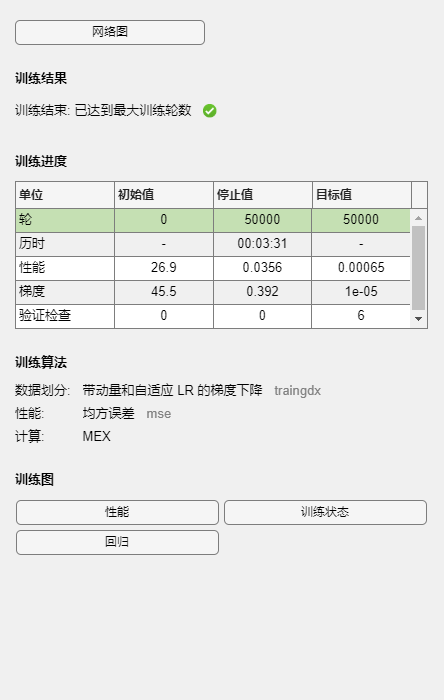

 
net.trainParam.show=1000;               %1000轮回显示一次结果
net.trainParam.Lr=0.05;                 %学习速度为0.05
net.trainParam.epochs=50000;           %最大训练轮回为50000次
net.trainParam.goal=0.65*10^(-3);     %均方误差
net=train(net,pn,tn);             %开始训练，其中pn,tn分别为输入输出样本

%利用原始数据对BP网络仿真
an=sim(net,pn);           %用训练好的模型进行仿真
a=postmnmx(an,mint,maxt); % 把仿真得到的数据还原为原始的数量级；

pnew=p;   %%输入自变量的参数，每一行表示一个自变量，列数表示预测的个数
pnewn=tramnmx(pnew,minp,maxp); %利用原始输入数据的归一化参数对新数据进行归一化；

          Use MAPMINMAX instead.
 


anewn=sim(net,pnewn);            %利用归一化后的数据进行仿真；
anew=postmnmx(anewn,mint,maxt)  %把仿真得到的数据还原为原始的数量级；

anew = 1.0e+06 *

    1.2357    1.2343    1.2338    1.2343    1.2356    1.2381    1.2417    1.2468    1.2535    1.2622    1.2733    1.2872    1.3043    1.3248    1.3490    1.3764    1.4062    1.4370    1.4665    1.4919    1.5099    1.5177    1.5132    1.4958    1.4663    1.4272    1.3820    1.3346    1.2887    1.2469    1.2108    1.1809    1.1571    1.1387    1.1249    1.1147    1.1075    1.1027    1.0996    1.0982    1.0982    1.0996    1.1025    1.1069    1.1130    1.1206    1.1294    1.1389    1.1481    1.1564


wucha=abs(t-anew)./t   %%%相对误差

wucha =     0.0570    0.0063    0.2169    0.0377    0.0659    0.0532    0.0264    0.0579    0.0746    0.1536    0.0323    0.1360    0.0432    0.0044    0.0512    0.0416    0.1026    0.0397    0.1091    0.1124    0.0068    0.0558    0.0450    0.0449    0.0391    0.0195    0.0141    0.0525    0.0982    0.0974    0.5028    0.1886    0.0267    0.0167    0.0401    0.0696    0.0272    0.2063    0.1624    0.1977    0.0048    0.3242    0.1732    0.1648    0.0000    0.0053    0.0219    0.0222    0.0363    0.1204


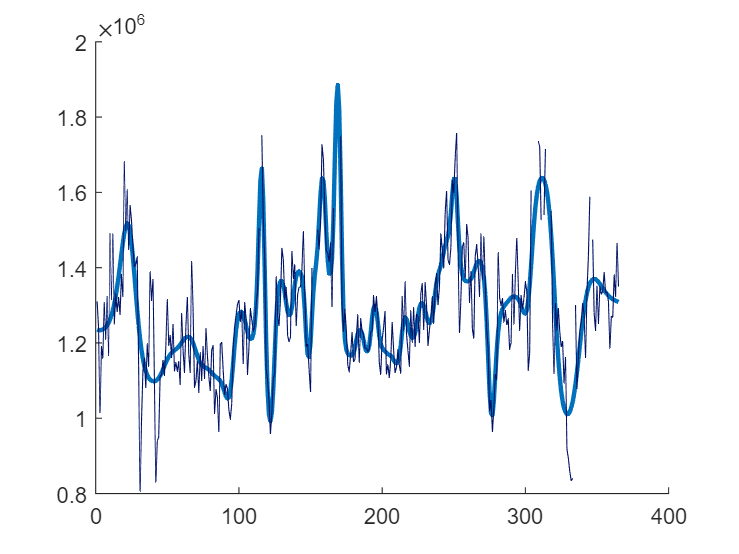

clf
hold on
plot(A,anew',LineWidth=2)
plot(t,"Color","#016");
hold off

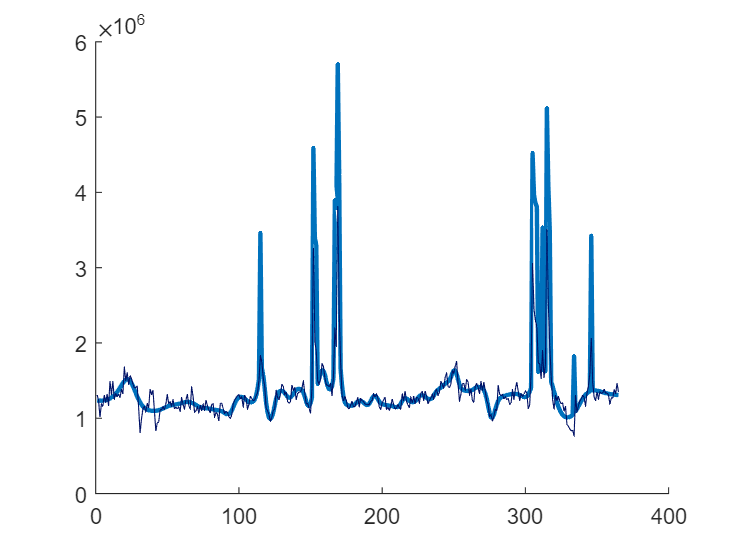

temp=anew;
mask = ones(size(altered));
mask(outliers) = 0;
mask = logical(mask);
altered(~mask) = 0;
temp=temp+save/2;

clf
hold on
plot(A,temp',LineWidth=2)
plot(save2/2,"Color","#016");
hold off

A=temp;%%%%自变量(货物总量)
y=b14e10(366:end);
y=y';
[n1,n]=size(A) %%%%自变量的个数

n1 = 1

n = 365

[m,m1]=size(y) %%%%因变量的个数

m = 365

m1 = 1

p=A';  %将所有自变量合并得到输入数据矩阵
t=y; %将所有因变量合并目标数据矩阵
%利用premnmx函数对数据进行归一化
 
[pn,minp,maxp,tn,mint,maxt]=premnmx(p,t); % 对于输入矩阵p和输出矩阵t进行归一化处理

          Use MAPMINMAX instead, type HELP PREMNMX for bug warning.
 


u=ones(n,1);
dx=[-1*u,1*u];                   %归一化处理后最小值为-1，最大值为1
%BP网络训练
net=newff(dx,[n,50,m],{'tansig','tansig','purelin'},'traingdx'); %建立模型，并用梯度下降法训练．

          See help for NEWFF to update calls to the new argument list.
 


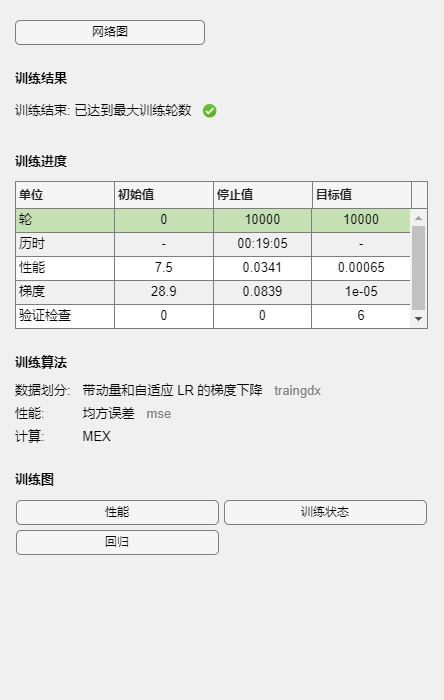

 
net.trainParam.show=1000;               %1000轮回显示一次结果
net.trainParam.Lr=0.2;                 %学习速度为0.05
net.trainParam.epochs=10000;           %最大训练轮回为50000次
net.trainParam.goal=0.65*10^(-3);     %均方误差
net=train(net,pn,tn);                   %开始训练，其中pn,tn分别为输入输出样本

%利用原始数据对BP网络仿真

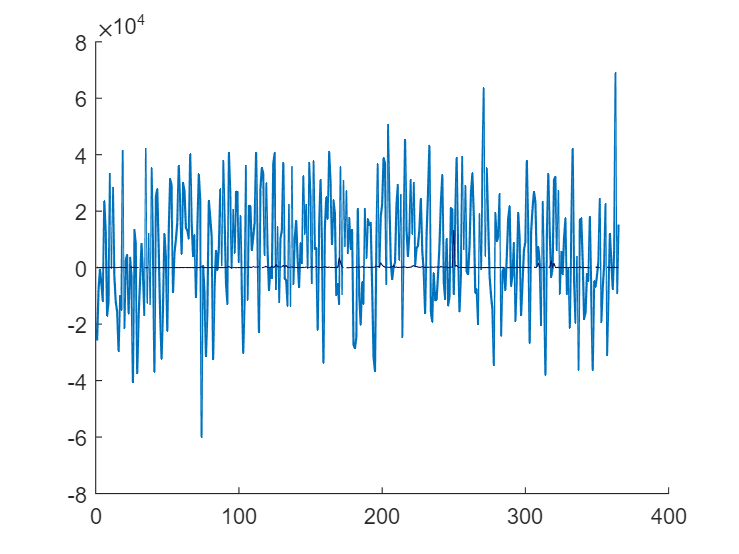

an=sim(net,pn);           %用训练好的模型进行仿真
a=postmnmx(an,mint,maxt); % 把仿真得到的数据还原为原始的数量级；
clf
hold on
plot(a,LineWidth=1)
plot(y,"Color","#016");
hold off

A=temp;%%%%自变量(货物总量)
y=b20e35(366:end);
y=y';
[n1,n]=size(A) %%%%自变量的个数

n1 = 1

n = 365

[m,m1]=size(y) %%%%因变量的个数

m = 365

m1 = 1

p=A';  %将所有自变量合并得到输入数据矩阵
t=y; %将所有因变量合并目标数据矩阵
%利用premnmx函数对数据进行归一化
 
[pn,minp,maxp,tn,mint,maxt]=premnmx(p,t); % 对于输入矩阵p和输出矩阵t进行归一化处理

          Use MAPMINMAX instead, type HELP PREMNMX for bug warning.
 


u=ones(n,1);
dx=[-1*u,1*u];                   %归一化处理后最小值为-1，最大值为1
%BP网络训练
net=newff(dx,[n,50,m],{'tansig','tansig','purelin'},'traingdx'); %建立模型，并用梯度下降法训练．

          See help for NEWFF to update calls to the new argument list.
 


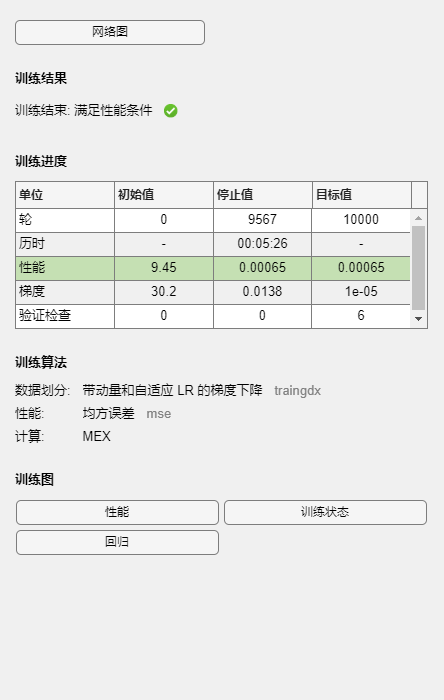

 
net.trainParam.show=1000;               %1000轮回显示一次结果
net.trainParam.Lr=0.2;                 %学习速度为0.05
net.trainParam.epochs=10000;           %最大训练轮回为50000次
net.trainParam.goal=0.65*10^(-3);     %均方误差
net=train(net,pn,tn);                   %开始训练，其中pn,tn分别为输入输出样本

%利用原始数据对BP网络仿真

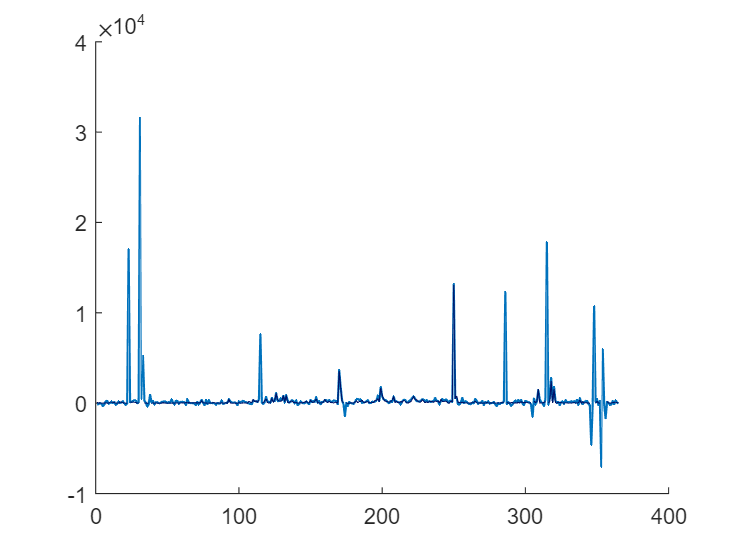

an=sim(net,pn);           %用训练好的模型进行仿真
a=postmnmx(an,mint,maxt); % 把仿真得到的数据还原为原始的数量级；
clf
hold on
plot(a,LineWidth=1)
plot(y,"Color","#016");
hold off

A=temp;%%%%自变量(货物总量)
y=b25e62(366:end);
y=y';
[n1,n]=size(A) %%%%自变量的个数

n1 = 1

n = 365

[m,m1]=size(y) %%%%因变量的个数

m = 365

m1 = 1

p=A';  %将所有自变量合并得到输入数据矩阵
t=y; %将所有因变量合并目标数据矩阵
%利用premnmx函数对数据进行归一化
 
[pn,minp,maxp,tn,mint,maxt]=premnmx(p,t); % 对于输入矩阵p和输出矩阵t进行归一化处理

          Use MAPMINMAX instead, type HELP PREMNMX for bug warning.
 


u=ones(n,1);
dx=[-1*u,1*u];                   %归一化处理后最小值为-1，最大值为1
%BP网络训练
net=newff(dx,[n,50,m],{'tansig','tansig','purelin'},'traingdx'); %建立模型，并用梯度下降法训练．

          See help for NEWFF to update calls to the new argument list.
 


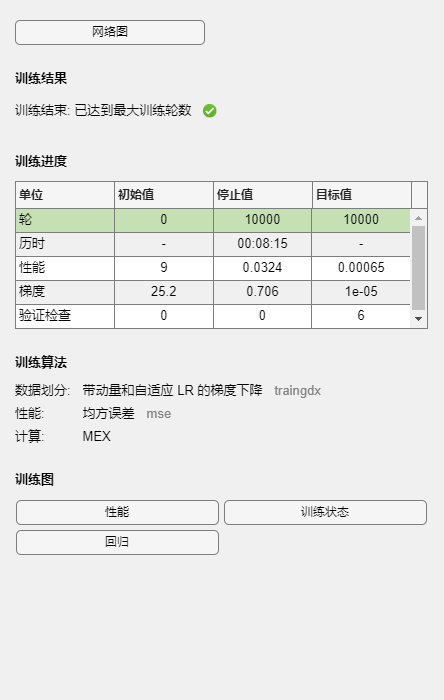

 
net.trainParam.show=1000;               %1000轮回显示一次结果
net.trainParam.Lr=0.2;                 %学习速度为0.05
net.trainParam.epochs=10000;           %最大训练轮回为50000次
net.trainParam.goal=0.65*10^(-3);     %均方误差
net=train(net,pn,tn);                   %开始训练，其中pn,tn分别为输入输出样本

%利用原始数据对BP网络仿真

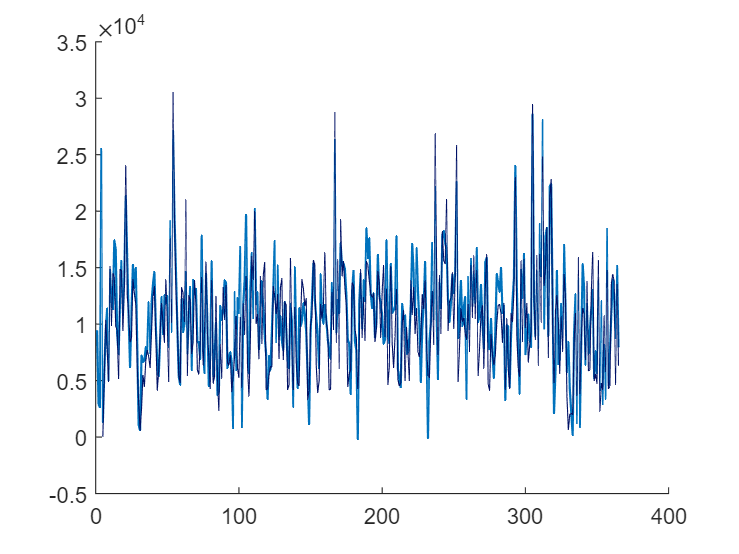

an=sim(net,pn);           %用训练好的模型进行仿真
a=postmnmx(an,mint,maxt); % 把仿真得到的数据还原为原始的数量级；
clf
hold on
plot(a,LineWidth=1)
plot(y,"Color","#016");
hold off